# Evaluación ejercicio 1

Calcula el vector de las velocidades lineales y angulares para el robot mostrado: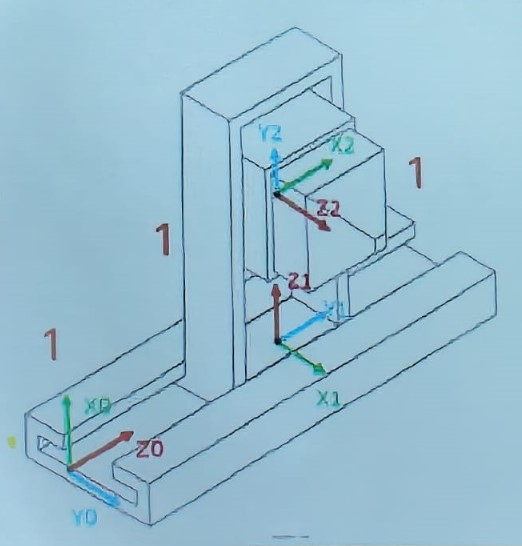

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms l1(t) l2(t) l3(t) t 

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Creamos el vector de coordenadas articulares
Q= [l1, l2, l3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Empezamos con una rotación de 90° en el eje y (tomando en cuenta que nuestra articulación se mueve sobre el eje y y nuestra z esta viendo hacia arriba) para la primera articulación para seguirla de una rotación de -90 en el eje x de la articulación con estos dos movimientos llegamos a la posición deseada en la articulación 3 por lo que ya no hay una rotación que hacer.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... 90º y1 
R(:,:,1)= [0  0 -1 ;
           0  1  0;
           1  0  0];


%Articulación 2 
%Posición de la articulación 3 respecto a 0
P(:,:,2)= [0 ; l3; l2];
%Matriz de rotación de la junta 3 respecto a 0.... -90º x2 
R(:,:,2)= [1  0  0;
           0  0  1;
           0  -1  0];

%Articulación 3 
%Posición de la articulación 3 respecto a 0
P(:,:,3)= [0 ; 0; 0];
R(:,:,3)= [1  0  0;
           0  1  0;
           0  0  1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(RO_inv(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación global T1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación local A2


/ 1,  0, 0,   0   \
|                 |
| 0,  0, 1, l3(t) |
|                 |
| 0, -1, 0, l2(t) |
|                 |
\ 0,  0, 0,   1   /



Matriz de Transformación global T2


/ 0, 1, 0, -l2(t) \
|                 |
| 0, 0, 1,  l3(t) |
|                 |
| 1, 0, 0,  l1(t) |
|                 |
\ 0, 0, 0,    1   /



Matriz de Transformación local A3


/ 1, 0, 0, 0 \
|            |
| 0, 1, 0, 0 |
|            |
| 0, 0, 1, 0 |
|            |
\ 0, 0, 0, 1 /



Matriz de Transformación global T3


/ 0, 1, 0, -l2(t) \
|                 |
| 0, 0, 1,  l3(t) |
|                 |
| 1, 0, 0,  l1(t) |
|                 |
\ 0, 0, 0,    1   /




%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a th1, th3 y th2
Jv11= functionalDerivative(PO(1,1,GDL), l1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);
%Derivadas parciales de y respecto a th1, th3 y th2
Jv21= functionalDerivative(PO(2,1,GDL), l1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);
%Derivadas parciales de z respecto a th1, th3 y th2
Jv31= functionalDerivative(PO(3,1,GDL), l1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
               Jv21 Jv22 Jv23;
               Jv31 Jv32 Jv33]);
pretty(jv_d);

/ 0, -1, 0 \
|          |
| 0,  0, 1 |
|          |
\ 1,  0, 0 /





%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, -1, 0 \
|          |
| 0,  0, 1 |
|          |
\ 1,  0, 0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 0, 0, 0 /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   ________ \
|    d       |
| - -- l2(t) |
|   dt       |
|            |
|  ________  |
|   d        |
|  -- l3(t)  |
|  dt        |
|            |
|  ________  |
|   d        |
|  -- l1(t)  |
\  dt        /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



RESULTADOS:

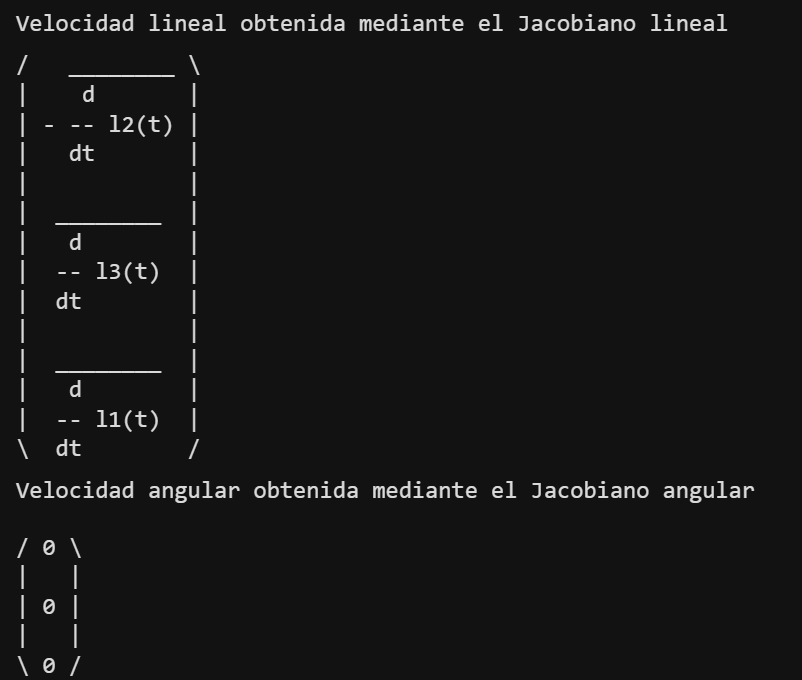

Podemos ver que para nuestra velocidad lineal nos que una variable l para cada eje, esto es debido a que en el robot el movimiento en cada eje es debido a una articulacion lineal del sistema.